# Mixed frequency model

**WARNING (BEAR 6 / BEARX): The structural identification cell at the bottom of this notebook (Cholesky on top of MixedFrequency) currently fails with a dimension-mismatch error inside mixed.estimator.MixedFrequency/initializeSampler/sampler line 217 (Phat = GAMMAs * Pt1 * GAMMAs' + ...). Root cause: the Kalman closure variable Pmean is only set inside one branch of the recursion around line 364, so on a second sampler invocation Pt = Pmean can be empty or wrongly sized. This is an upstream toolbox bug, not a tutorial issue. The reduced-form path (modelR1.presample) works fine. See test6_mixedFrequency.m and BEARX_PATCHES.md §1bis for details.**

**DATA NOTE: mixed_frequency_data_transformed.csv has the low-frequency series ygdp forward-filled to every month. mixed.estimator.MixedFrequency expects NaN on non-quarter-end rows. Add this snippet after the tablex.fromFile call to mask the forward-fill: months = month(inputTbl.Time); inputTbl.ygdp(~ismember(months,[3,6,9,12])) = NaN;**

## Housekeeping

clear
close all
  
import mixed.*

## Convenience functions

The `extremesFunc` function compresses any number of samples (draws from the posterior) into two numbers - the minimum and the maximum.

percentiles = [10, 50, 90];

prctileFunc = @(x) prctile(x, percentiles, 2);

extremesFunc = @(x) [min(x, [], 2), max(x, [], 2)];

medianFunc = @(x) median(x, 2);

defaultColors = get(0, "defaultAxesColorOrder");

## Number of Samples

numPresampled = 1000;

## Prepare meta information for the models

The meta information is almost identical to that of the base model, except that it distinguishes between two types of endogenous variables:

**highFrequencyNames** – names of high-frequency variables; their frequency determines the frequency of the final model (currently, only monthly data are supported).

**lowFrequencyNames** – names of low-frequency variables (currently, only quarterly data are supported).

**Important note**: the model does not allow the presence of exogenous variables other than the intercept.


estimStart = datex.m(2001,1);
estimEnd = datex.m(2021,2);
estimSpan = datex.span(estimStart, estimEnd);

meta = Meta( ...
    highFrequencyNames=["ipi", "ZEW", "DAX", "ifoclimate",...
        "ifoexpectations", "Retail", "Manufacturingsales",...
    	"Autprod", "Worldtrade", "WorldIP"], ...
    lowFrequencyNames="ygdp", ...
    order=6, ...
    intercept=true, ...
    estimationSpan=estimSpan, ...
    identificationHorizon=12 ...
);


## Specifying and loading input data

inputTbl = tablex.fromFile("data/mixed_frequency_data_transformed.csv");

% Keep ygdp only at the end of each quarter (Mar/Jun/Sep/Dec).
months = month(inputTbl.Time);
isQuarterEnd = ismember(months, [3, 6, 9, 12]);
inputTbl.ygdp(~isQuarterEnd) = NaN;

dataH = DataHolder(meta, inputTbl);

## Estimation/sampling of the reduced form model 

Similarly to plain BVARs the mixed frequency model also have 5 hyperparameters which are used for generating Minnesota type dummy observation

**MixedLambda1 (0.1) –** Overall tightness, controls overall shrinkage of coefficients toward prior means.

**MixedLambda2 (3.4) – **Lag decay, governs how rapidly higher-lag coefficients are shrunk

**MixedLambda3 (1) – **Covariance tightness, strength of prior on residual covariance structure.

**MixedLambda4 (3.4) – **Constant tightness, shrinkage applied to the intercept term.

**MixedLambda5 (14.76) – **Cross-variable shrinkage, controls correlation strength across variable coefficients.

estimatorR1 = estimator.MixedFrequency(meta)

estimatorR1 =   MixedFrequency with properties:

                Settings: [1×1 mixed.estimator.settings.MixedFrequency]
             Description: "Mixed-frequency VAR"
                Category: "Specialized estimators"
           HasCrossUnits: 0
         CanBeIdentified: 1
          CanHaveDummies: 0
                 Sampler: []
           SampleCounter: 0
           HistoryDrawer: []
     UnconditionalDrawer: []
       ConditionalDrawer: []
    IdentificationDrawer: []
          ShortClassName: 'MixedFrequency'
         BeenInitialized: 0



modelR1 = ReducedForm( ...
    meta=meta ...
    , dataHolder=dataH ...
    , estimator=estimatorR1 ...
);

modelR1.initialize();
info0 = modelR1.presample(numPresampled);


 Presampling from posterior (MixedFrequency) [1000]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 



modelR1.Presampled{1}.beta

ans = 1.0e+04 *

    0.0001
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0001
    0.0000
   -0.0000
   -0.0000
   -0.0000



%% NOTE on the structural identification step
% The original t6_mixedFrequency.mlx Live Script continues with a Cholesky
% identification cell:
%
%   identChol = identifier.Cholesky(ordering=[]);
%   modelS1   = Structural(reducedForm=modelR1, identifier=identChol);
%   modelS1.initialize();
%   modelS1.presample(numPresampled);
%
% That cell fails with a dimension-mismatch error inside
% mixed.estimator.MixedFrequency/initializeSampler/sampler (line 217):
%   Phat = GAMMAs * Pt1 * GAMMAs' + GAMMAu * sig_qq * GAMMAu';
%
% Root cause: the Kalman filter closure stores Pmean only inside one branch
% of the recursion (around line 364). On a second sampler invocation -
% which the structural identifier triggers via redSampler() - Pt is
% restored from Pmean, which can be [] or wrongly sized. This is an
% upstream toolbox bug in mixed.estimator.MixedFrequency, not in the
% tutorial. Reduced-form mixed-frequency works fine, so this script
% intentionally stops here.

fprintf("\ntest6_mixedFrequency completed (reduced-form only).\n");

## Running Unconditional forecast 

### Setting up the forecast range and run the forecast

fcastStart = datex.shift(modelR1.Meta.EstimationEnd, -10); %The forecast starts 10 periods prior to the end of the estimation span.
fcastEnd = datex.shift(modelR1.Meta.EstimationEnd, 0); %The forecast ends at the end of the estimation window.
fcastSpan = datex.span(fcastStart, fcastEnd);

fcastStart, fcastEnd

fcastStart = datetime
   2020-04


fcastEnd = datetime
   2021-02



fcastTbx = modelR1.forecast(fcastSpan);
fcastPrctileTbx = tablex.apply(fcastTbx, prctileFunc);
fcastPrctileTbx = tablex.flatten(fcastPrctileTbx); %keeping only the pctiles set at the beginning of the file (10, 50, 90)



### Visualize the unconditional forecast

% 
% chartpack.forecastPercentiles( ...
%     fcastPrctileTbx, modelR1, FigureTitle ="Unconditional forecast")

## Identification

### Cholesky

You can use the Cholesky decomposition also with a different ordering of endogenous variables than in the meta specification. However, if the trailing part of the order matches the meta order, you may omit that portion.

#### Setting up the identifier


identChol = identifier.Cholesky(ordering=[]); 

modelS1 = Structural(reducedForm=modelR1, identifier=identChol);
modelS1.initialize();

info0 = modelS1.presample(numPresampled);


 Presampling from posterior (MixedFrequency) [1000]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 



modelS1.Presampled{1}

ans = struct with fields:
                  beta: [737×1 double]
                 sigma: [121×1 double]
       initForForfcast: [248×11 double]
    IdentificationDraw: [1×1 struct]
                     D: [11×11 double]


#### Checking transition matrices

modelS1.Presampled{1}.IdentificationDraw

ans = struct with fields:
        A: {12×1 cell}
        C: {12×1 cell}
    Sigma: [11×11 double]


modelS1.Presampled{1}.IdentificationDraw.A{1,1}

ans = 1.0e+04 *

    0.0001    0.0004    0.1288    0.0009    0.0000    0.0000    0.0002    0.0002    0.0000    0.0000   -0.0000
    0.0000    0.0001   -0.0110   -0.0001    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000
    0.0000   -0.0004   -0.0791   -0.0005    0.0000    0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000
    0.0000    0.0067    1.3676    0.0092    0.0003   -0.0000    0.0015    0.0013   -0.0000   -0.0000    0.0000
    0.0000   -0.0013   -0.2628   -0.0017    0.0001    0.0000   -0.0003   -0.0001    0.0000    0.0000   -0.0000
    0.0000    0.0017    0.3047    0.0020    0.0001    0.0000    0.0003    0.0002   -0.0000   -0.0000    0.0000
   -0.0000    0.0005    0.1009    0.0007    0.0000    0.0000    0.0002    0.0002    0.0000   -0.0000   -0.0000
   -0.0000    0.0000    0.0069    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000
    0.0000   -0.0028   -0.5496   -0.0036   -0.0001   -0.0000   -0.0006   -0.0003    0.0001    0

modelS1.Presampled{1}.IdentificationDraw.A{2,1}

ans = 1.0e+04 *

    0.0001    0.0004    0.1288    0.0009    0.0000    0.0000    0.0002    0.0002    0.0000    0.0000   -0.0000
    0.0000    0.0001   -0.0110   -0.0001    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000
    0.0000   -0.0004   -0.0791   -0.0005    0.0000    0.0000   -0.0001   -0.0000    0.0000    0.0000   -0.0000
    0.0000    0.0067    1.3676    0.0092    0.0003   -0.0000    0.0015    0.0013   -0.0000   -0.0000    0.0000
    0.0000   -0.0013   -0.2628   -0.0017    0.0001    0.0000   -0.0003   -0.0001    0.0000    0.0000   -0.0000
    0.0000    0.0017    0.3047    0.0020    0.0001    0.0000    0.0003    0.0002   -0.0000   -0.0000    0.0000
   -0.0000    0.0005    0.1009    0.0007    0.0000    0.0000    0.0002    0.0002    0.0000   -0.0000   -0.0000
   -0.0000    0.0000    0.0069    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000
    0.0000   -0.0028   -0.5496   -0.0036   -0.0001   -0.0000   -0.0006   -0.0003    0.0001    0

#### Checking scaling matrix

modelS1.Presampled{1}.D

ans =     0.0155   -1.1172 -211.8302   -1.3974   -0.0265    0.0065   -0.2323   -0.1033    0.0054    0.0065    0.0047
         0    2.4209  475.2362    3.1462    0.0834   -0.0060    0.5246    0.3015   -0.0083   -0.0058   -0.0014
         0         0   18.8609    0.1233   -0.0041    0.0032    0.0191    0.0189   -0.0017    0.0007    0.0028
         0         0         0    0.0095    0.0202    0.0028    0.0020    0.0346    0.0030    0.0013    0.0029
         0         0         0         0    0.0167    0.0004    0.0024    0.0015    0.0006   -0.0002    0.0020
         0         0         0         0         0    0.0109   -0.0027    0.0226   -0.0001   -0.0000    0.0017
         0         0         0         0         0         0    0.0191   -0.0014    0.0018   -0.0000   -0.0009
         0         0         0         0         0         0         0    0.1072    0.0009    0.0009   -0.0003
         0         0         0         0         0         0         0         0    0.0124   -0.0001   -0.

modelS1.Presampled{2}.D

ans =     0.0156   -0.9367 -175.3555   -1.1567   -0.0208    0.0048   -0.1897   -0.0889    0.0042    0.0062    0.0034
         0    2.3574  463.3190    3.0659    0.0798   -0.0059    0.5128    0.2864   -0.0074   -0.0053   -0.0023
         0         0   19.8655    0.1284   -0.0064    0.0014    0.0236    0.0208   -0.0004    0.0006    0.0007
         0         0         0    0.0089    0.0186    0.0020   -0.0005    0.0230    0.0010    0.0013    0.0019
         0         0         0         0    0.0156    0.0010    0.0034    0.0005    0.0021    0.0003    0.0011
         0         0         0         0         0    0.0110   -0.0010    0.0201   -0.0006    0.0001    0.0039
         0         0         0         0         0         0    0.0183    0.0040    0.0016    0.0004    0.0013
         0         0         0         0         0         0         0    0.0974    0.0004    0.0006    0.0014
         0         0         0         0         0         0         0         0    0.0109    0.0000    0.

## Impulse respones (IRF)

### Cholesky

respTbl1 = modelS1.simulateResponses();


  (MixedFrequency) [1000]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 



respTbl1 = tablex.apply(respTbl1, prctileFunc);
respTbl1 = tablex.flatten(respTbl1);

respTbl1

respTbl1 = 13×121 timetable
     Time                   ipi___ipi_shock                              ipi___ZEW_shock                              ipi___DAX_shock                          ipi___ifoclimate_shock                     ipi___ifoexpectations_shock                      ipi___Retail_shock                     ipi___Manufacturingsales_shock                     ipi___Autprod_shock                        ipi___Worldtrade_shock                         ipi___WorldIP_shock                           ipi___ygdp_shock                              ZEW___ipi_shock                              ZEW___ZEW_shock                              ZEW___DAX_shock                          ZEW___ifoclimate_shock                     

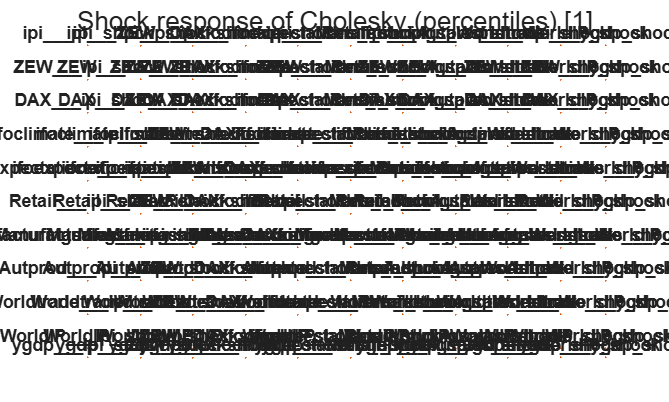


chartpack.responsePercentiles( ...
    respTbl1, modelS1 ...
    , "figureTitle", "Shock response of Cholesky (percentiles)" ...
);

## **Historical shock decomposition**

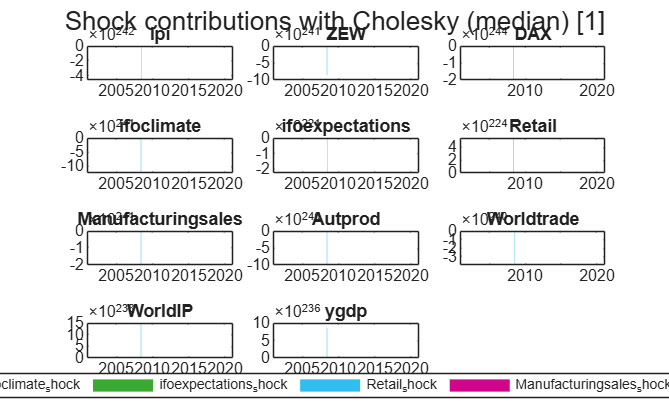

histContTbx = modelS1.calculateContributions();

histContMedTbx = tablex.apply(histContTbx, medianFunc);

chartpack.contributionsMedian( ...
    histContMedTbx, modelS1 ...
    , "figureTitle", "Shock contributions with Cholesky (median)" ...
);

## **Unconditional forecast shock decomposition**

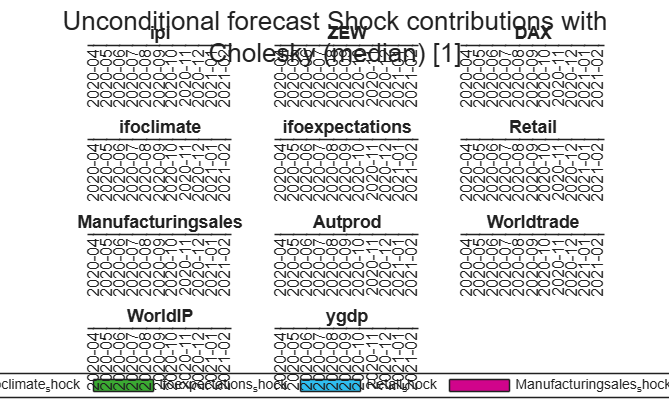


[uncFcastTbl1, uncFcastContribTbl1] = modelS1.forecast( ...
    fcastSpan, ...
    contributions=true ...
);


contMedTbx = tablex.apply(uncFcastContribTbl1, medianFunc);

chartpack.contributionsMedian( ...
    contMedTbx, modelS1 ...
    , "figureTitle", "Unconditional forecast Shock contributions with Cholesky (median)" ...
);

## **FEVD**

fevdTbx = modelS1.calculateFEVD();


  (MixedFrequency) [1000]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 



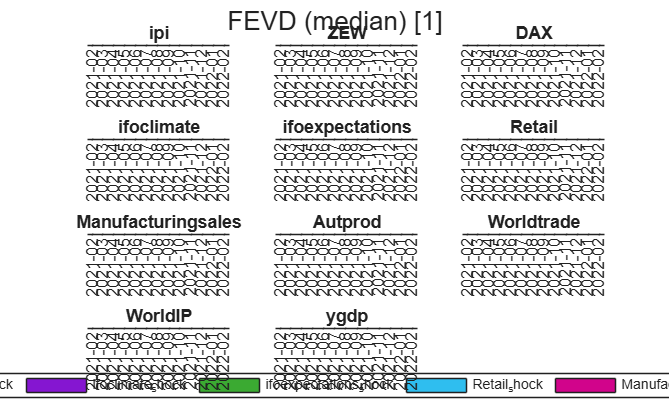


fevdMedTbx = tablex.apply(fevdTbx, medianFunc);

chartpack.contributionsMedian( ...
    fevdMedTbx, modelS1 ...
    , "figureTitle", "FEVD (median)" ...
);